VEIN REMOVAL

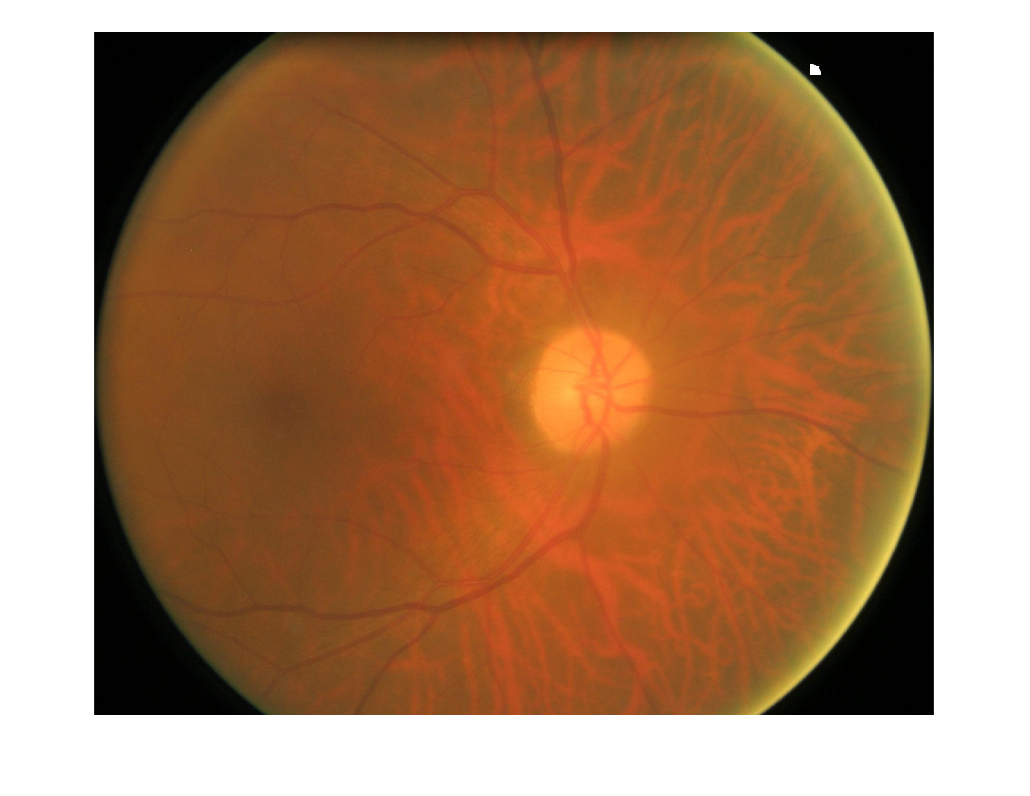

close all
clear
metadata=readtable("metadata.csv");

[im_sin,~,~] = find(metadata.quality==0);
sin = metadata(im_sin,:);
RAN=randi([1,height(sin)]);

im_sin_str = string(sin.image(RAN));
I= imread(im_sin_str);

figure
imshow(I,[])

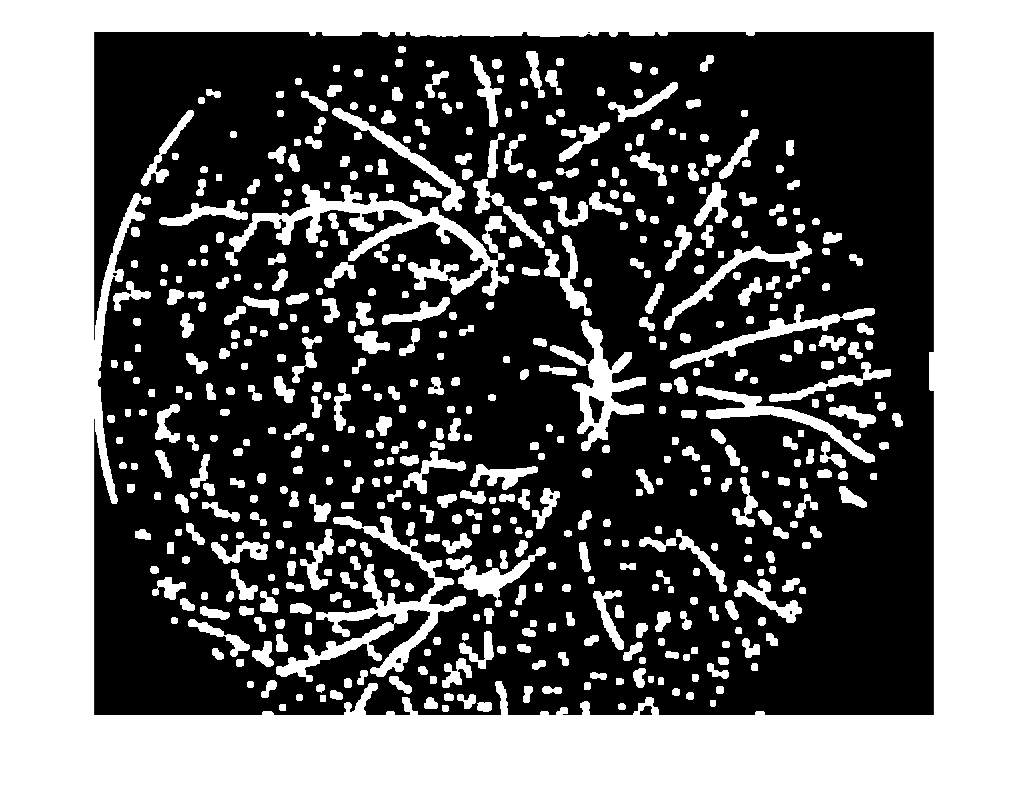

    im_rgb = im2double(I);
    im_mask = im_rgb(:,:,2) > (20/255);
    
    im_mask = double(imerode(im_mask, strel('disk',3)));
    
    % Extract green channel
    im_green = im_rgb(:,:,2);

    % CLAHE enhancement
    im_enh = adapthisteq(im_green,'numTiles',[8 8],'nBins',128);

    % Replace the black background of the fundus image with the mean of
    % 3 randomly selected (50, 50, 50) background matrices
    [im_enh1, mean_val] = replace_black_ring(im_enh,im_mask);

    % Negative
    im_gray = imcomplement(im_enh1); 

    % Use Top-Hat transform
    se = strel('disk',10);
    im_top = imtophat(im_gray,se);
    im_top_8=im2uint8(im_top);
    im_top_8=imadjust(im_top_8);
    im_thre=im_top_8>100;
    se = strel('disk',5);
    im_thre=imopen(im_thre,se);
    se = strel('disk',7);
    im_thre=imdilate(im_thre,se);
    se = strel('disk',5);
    im_thre=imclose(im_thre,se);
    
    % OTSU Thresholding 
%     level = graythresh(im_top_8);
%     im_thre = imbinarize(im_top,level) & im_mask;
% 
%     % Delete small connected component
%     im_rmpix = bwareaopen(im_thre,1000,8);
%     im_rmpix = imopen(im_rmpix,strel('disk',50));
%     
%     % Find thick vessels based on im_gray, im_rmpix and mean_val
%     % We can use im_green instead of mean_val but by using mean_val,
%     % running time very decrease 
%     % [im_sel] = vessel_point_selected(im_gray,im_rmpix,im_green);
%     [im_sel] = vessel_point_selected(im_gray,im_rmpix,mean_val);
% 
%     % Find thin vessels using MF and FDoG filter 
%     im_thin_vess = MatchFilterWithGaussDerivative(im_enh, 1, 4, 12, im_mask, 2.3, 30);
% 
%     % Based on im_sel and im_thin_vess, we decide to find the final vessels
%     [im_final] = combine_thin_vessel(im_thin_vess,im_sel);
%     
    
    
    figure
    imshow(im_thre,[])

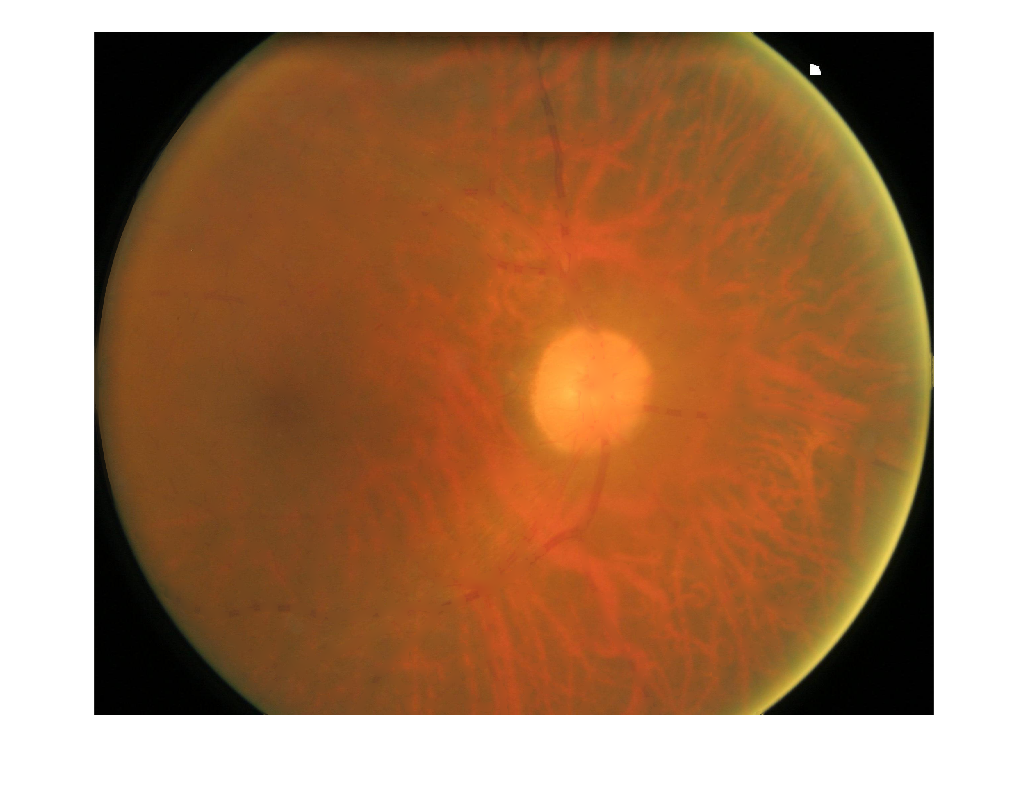

    im_sin=inpaintCoherent(I,im_thre,"SmoothingFactor",4,"Radius",30);
    figure
    imshow(im_sin,[])